%Mostafa's Rib Thickness 
clc
clear
close

load('liftSurfGeom.mat');
load('Effective_thickness_VTP.mat')

t_e = t_eff;
% Now, it is possible to discretise the wing span into increments of 's':
span = b_VT; % Wing Span/2 (m)

%RUN WINGCOVER.MAT
disc = z

disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


rib_spacing = 0.6;
s=rib_spacing;
rib_coordinates=0:0.6:span

rib_coordinates =          0    0.6000    1.2000    1.8000    2.4000    3.0000    3.6000    4.2000    4.8000    5.4000


s_r=rib_coordinates

s_r =          0    0.6000    1.2000    1.8000    2.4000    3.0000    3.6000    4.2000    4.8000    5.4000


% The chord distribution along the span is:

root_chord=c_r_VT;
tip_chord=c_r_VT*0.4;

c_r = ((tip_chord-root_chord)/span).*rib_coordinates + root_chord;
c_r = c_r*0.43;

no_ribs = length(rib_coordinates);

%% RC's Remerz function to find BM at each rib:
% Bending Moments:

BM(1)=BM_VT(1)

BM = 6.7928e+04

BM(2)=BM_VT(61)

BM = 1.0e+04 *

    6.7928    5.1894


BM(3)=BM_VT(121)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201


BM(4)=BM_VT(181)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201    2.6807


BM(5)=BM_VT(241)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201    2.6807    1.7640


BM(6)=BM_VT(301)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201    2.6807    1.7640    1.0598


BM(7)=BM_VT(361)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201    2.6807    1.7640    1.0598    0.5538


BM(8)=BM_VT(421)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201    2.6807    1.7640    1.0598    0.5538    0.2274


BM(9)=BM_VT(481)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201    2.6807    1.7640    1.0598    0.5538    0.2274    0.0552


BM(10)=BM_VT(541)

BM = 1.0e+04 *

    6.7928    5.1894    3.8201    2.6807    1.7640    1.0598    0.5538    0.2274    0.0552    0.0014


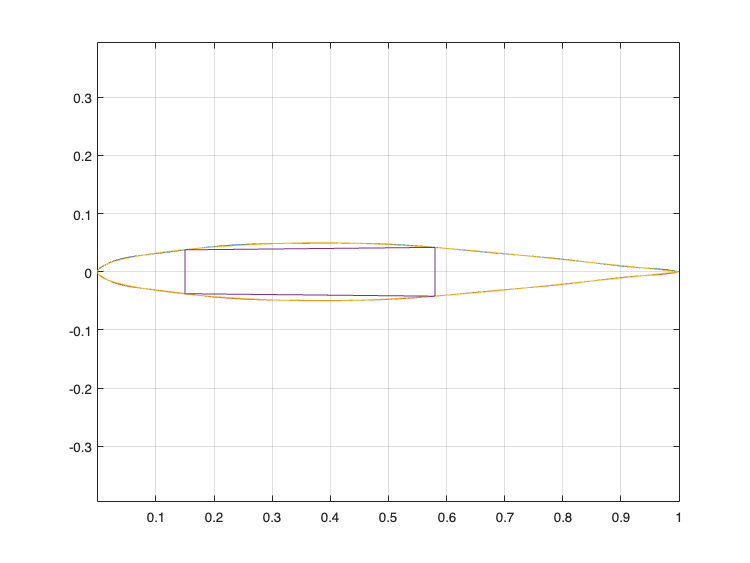


% Implementing Remi's script to find the coordinates of the wingbox, for a
% chord of 1
figure
coords=wingbox(VT);


figure
hold on
plot(s_r,c_r,'x')
ylabel("Rib chord")
xlabel("Rib span (location)")
legend('Ribs, evenly distributed','Constraints')

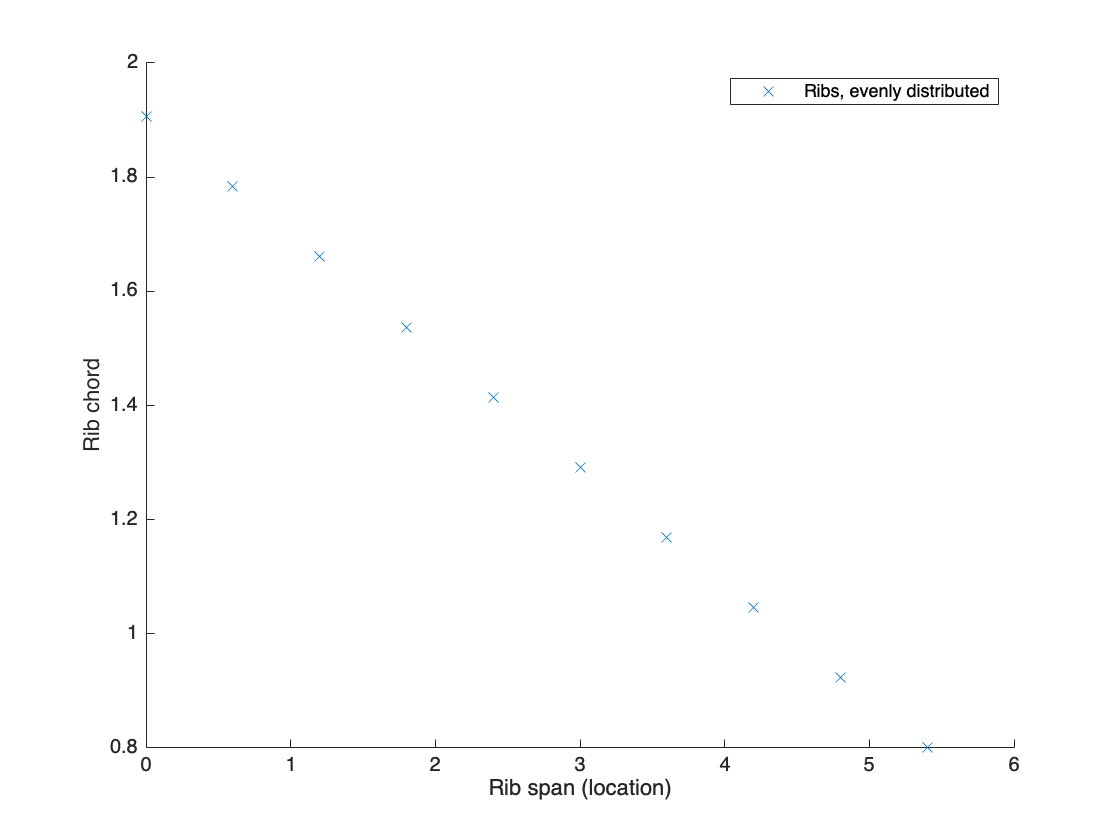

hold off

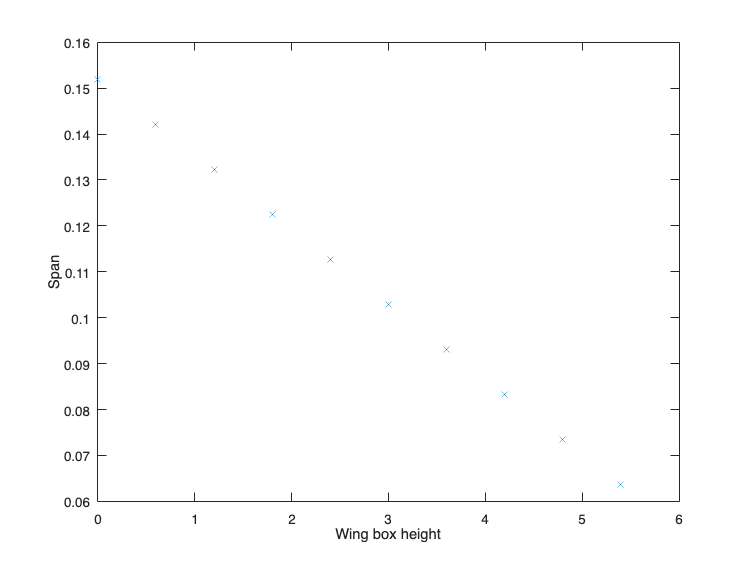


% Now, it is possible to find the wing box height 
h_c=zeros(1,no_ribs); % Depth of wing box along chord (m)

for j=1:length(c_r)
    h_c(j) = c_r(j)*((coords(1,2)-coords(2,2))+(coords(4,2)-coords(3,2)))/2;
end

figure
plot(s_r,h_c,'x')
ylabel("Span")
xlabel("Wing box height")


%% Crushing 

% To determine the rib thickness, it is necessary to equate the yield
% stress of the material to the critical buckling stress of the material

% From Zahra, the critical buckling stress is given by: 3.62E(t/h)^2 where
% E is Young's Modulus, t is rib thickness, and h is wing box depth

% From Daqing, the critical yield stress is given by: F/t*c where F is the
% crush force (see video 11:40), and c is chord at rib position.



% t_e = []; % Effective length (m)
% for l=1:length(c_r)
%     t_e(l)=0.002;
% end
% 
E = 7.35*10^10; % Young's Modulus (Pa) - Used Al currently
I=[];
t_r=[];
% 
% % Crushing force:
% 
I = (c_r .* t_e.^3)./12 + (c_r .* t_e .* (h_c./2).^2);
F = (BM.^2 .* s .* h_c .* t_e .* c_r) ./ (2 .* E .* I.^2) 

F = 1.0e+03 *

    6.9107    5.2644    3.7948    2.5408    1.5347    0.7963    0.3241    0.0851    0.0083    0.0000


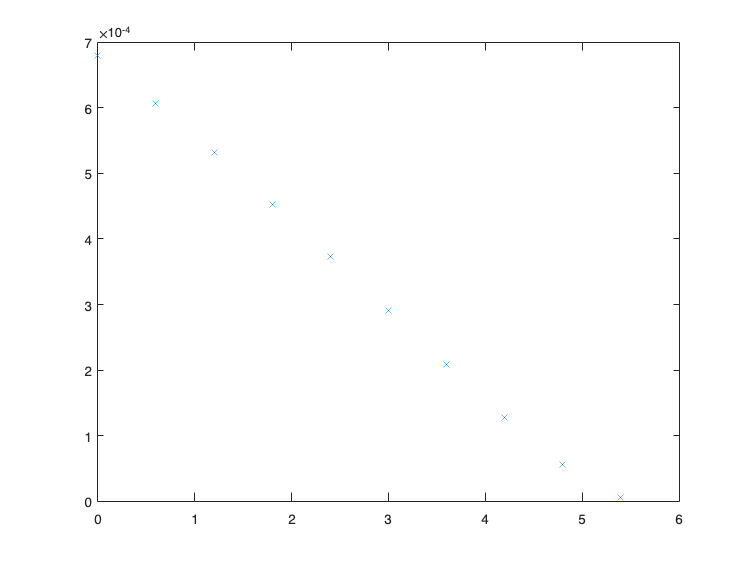

t_r = ((F .* h_c.^2)./(3.62.*E.*c_r)).^(1/3);
% 
% figure
plot(s_r,t_r,'x')

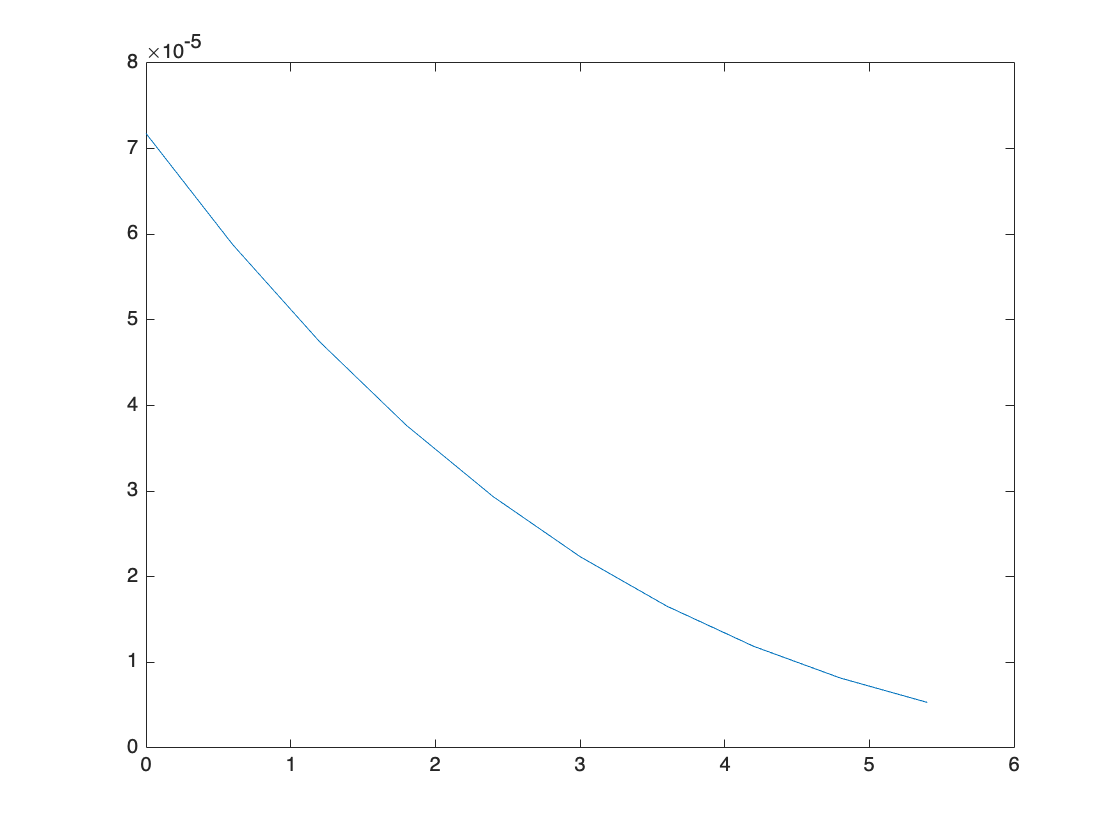

% xlabel("Rib Span")
% ylabel("Rib Thickness")

plot(s_r,I)

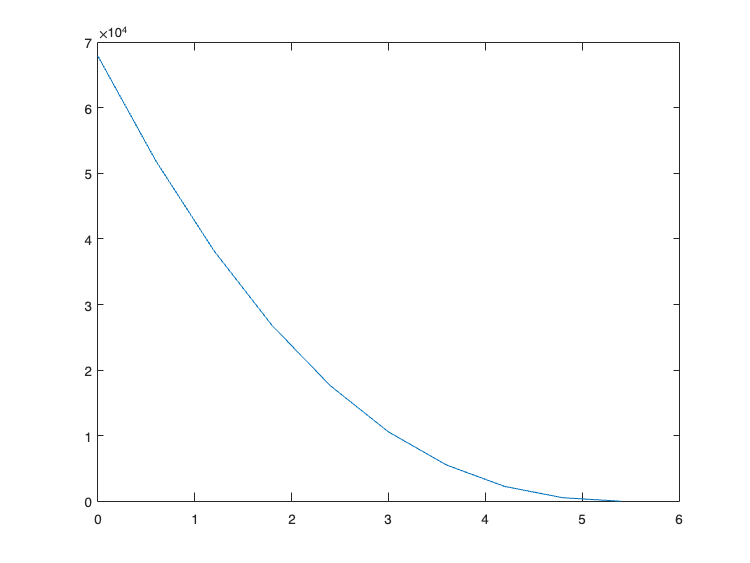

plot(s_r,BM)

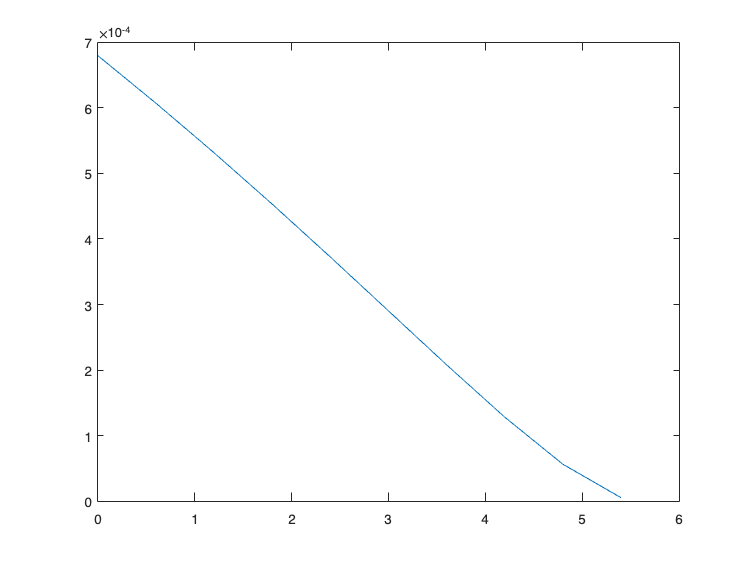

plot(s_r,t_r)

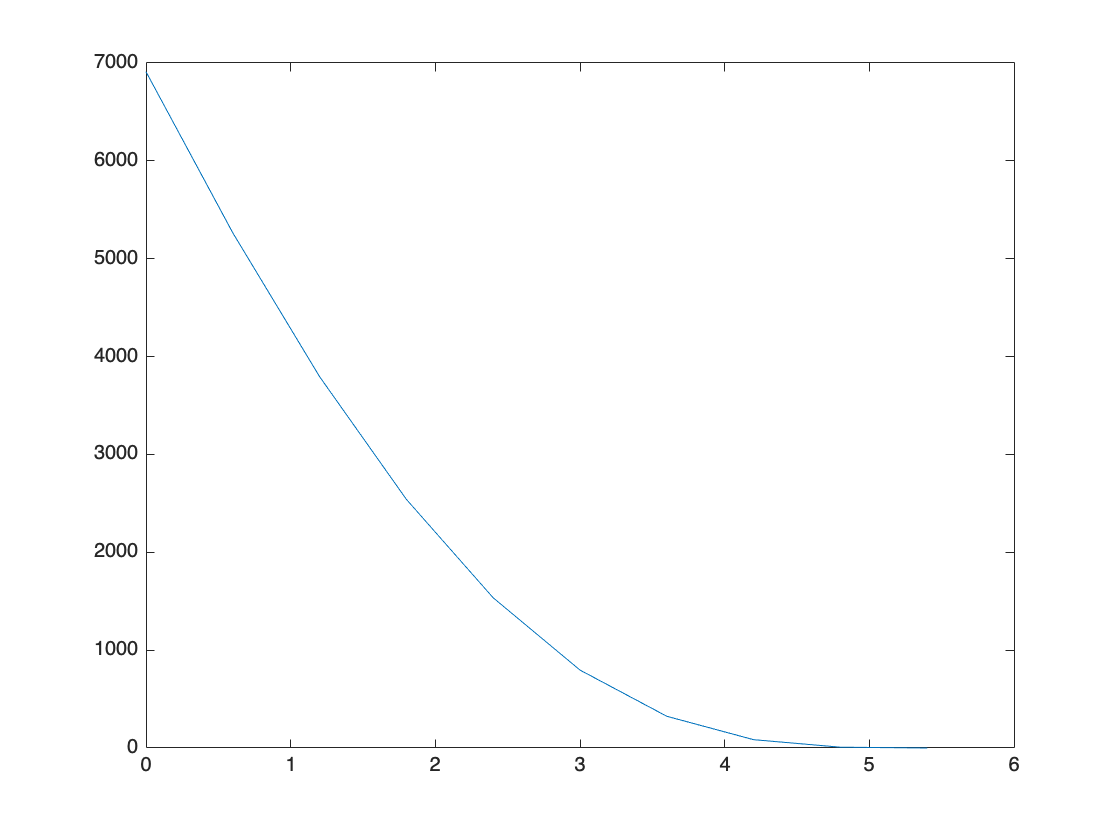

plot(s_r,F)